g = 9.8;
M = 1; %kg
R = 3; %Ohm
L = 1; %H

y0 = 1;

A = [0, 1, 0;
    2*g/y0, 0, (-2/y0)*sqrt(g/M);
    0, 0, -R/L];

b = [0; 0; 1/L];

c = [1; 0; 0];

d = 0;

eig(A)

ans =     4.4272
   -4.4272
   -3.0000


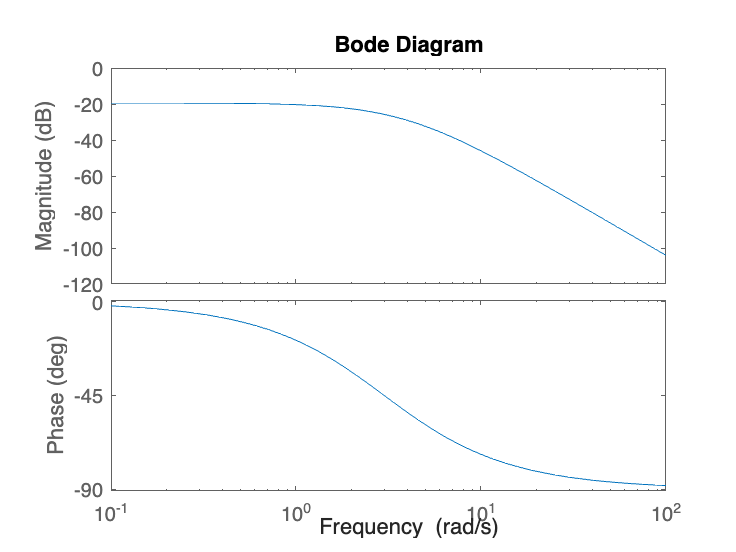


sys = ss(A, b, c', d);
sys_tf = ss2tf(A, b, c', d);

bode(sys)